对于一个二阶微分方程：


$$\ddot{x}+2\zeta\omega_n\dot{x}+\omega_n^2x=\omega_n^2u$$


作拉氏变换：


$$s^2-sX(0)-{X(0)}' + 2\zeta\omega_n[sX-X(0)]+\omega_n^2X=\omega_n^2U$$


假设初始条件为零，


$$s^2 + 2\zeta\omega_nsX+\omega_n^2X=\omega_n^2U$$


传递函数为：


$$G(s)=\frac{X(s)}{U(s)}=\frac{\omega_n^2}{s^2+2\zeta\omega_n+\omega_n^2}$$


取状态向量$x_1=x, x_2=\dot{x}
$，状态方程为：


$$\dot{x_1}=\dot{x}=x_2
\\ \dot{x_2}=\ddot{x}=-\omega_n^2x_1-2\zeta\omega_nx_2+\omega_n^2u$$


写为紧凑形式：


$$\dot{x}=Ax+Bu$$


clc
clear
close all

global Wn zeta
Wn = 1;         % 固有频率 1rad/s
zeta = 0.5;     % 欠阻尼
Num = [Wn^2];
Den = [1, 2*zeta*Wn, Wn^2]; 

sys = tf(Num, Den)

sys =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



pole(sys)       % 系统有两个具有负实部的极点，系统稳定

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i


## 不使用控制器

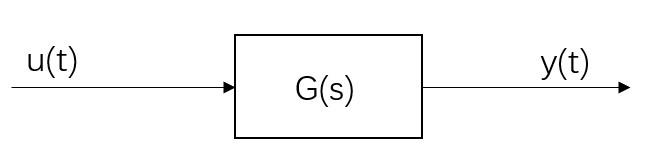

开环控制

**输入信号为阶跃信号(阶跃响应)**

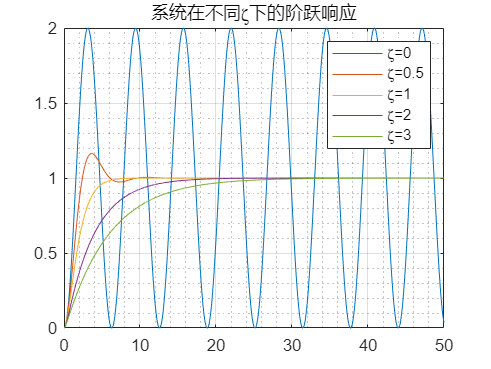

figure(1)
t = 0:0.01:50;
zet = [0,0.5,1,2,3];
for i = 1:length(zet)
    sys_temp = tf([Wn^2], [1, 2*zet(i)*Wn, Wn^2]);
    out = step(sys_temp, t);
    plot(t, out)
    hold on
end
title("系统在不同\zeta下的阶跃响应")
legend("\zeta=0","\zeta=0.5","\zeta=1","\zeta=2","\zeta=3")
grid on
grid minor
hold off

阻尼系数$\zeta
$大于0小于1，称为欠阻尼，系统会发生振荡；

阻尼系数$\zeta
$等于1，称为临界阻尼，系统恰好不会发生振荡；

阻尼系数$\zeta
$大于1，称为过阻尼，系统不会发生振荡，$\zeta
$越大，系统的调节时间越长。

**输入信号为方波**

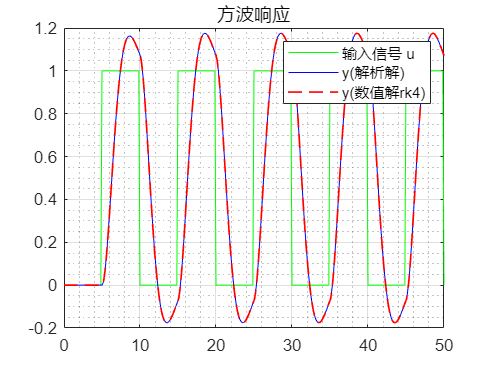

figure(2)
% 使用Matlab内置函数lsim()求系统响应
global tau;
tau = 10;
Tmax = 50;
[u,t] = gensig('square',tau,Tmax);
[ys,ts] = lsim(sys,u,t);
plot(t, u, 'g', ts, ys, 'b')
grid on
grid minor
hold on

% 使用龙格库塔法求解系统响应
X0 = [0;0];     % 初始条件
h = 0.01;
T = 0:h:Tmax;

[T,X] = lab_ode_rk4(@fnc,T,X0);

plot(T, X(1,:),'r--', "LineWidth",1) % 状态向量x1为系统的输出
title("方波响应")
legend("输入信号 u","y(解析解)","y(数值解rk4)")
hold off

        可以看出h合适的情况下，龙格库塔法的精度很好。

function [T,X] = lab_ode_rk4(fnc,T,X0)
    N=length(T);
    h=T(2)-T(1);
    X=zeros(length(X0),N);
    X(:,1)=X0;
    for i =2:N        
        X_k = X(:,i-1);
        t_k = T(i-1);
        
        K1=fnc(t_k,X_k);
        K2=fnc(t_k+h/2,X_k+h/2*K1);
        K3=fnc(t_k+h/2,X_k+h/2*K2);
        K4=fnc(t_k+h,X_k+h*K3);
        
        X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
    end
end

function dx = fnc(t,x)
    global Wn zeta tau
    
    % 生成方波控制信号
    t = mod(t, tau);
    if t <= 5 
        u = 0;
    else
        u = 1;
    end
    
    dx = zeros(length(x), 1);
    dx(1) = x(2);
    dx(2) = -Wn^2*x(1) - 2*zeta*Wn*x(2) + Wn^2*u;
end